% Load IBS data
load('F:\data\VALIDEIT09\eit\MIK_P_O\eitV2.mat');
crs = NonInvEIT(eit);

imgFilt = applyFilter(crs,crs.ImgRaw,crs.Fs,false);
imgFilt(isnan(imgFilt)) = 0;

load('F:\data\VALIDEIT09\eit\cct.mat');

transformEitToCt(crs, cct.ElecAngle, cct.ElecContour);
rois = getCtROIs(crs, cct.FlatROIs);
eitROIs = getEitROIs(crs, imgFilt);
t = crs.T;

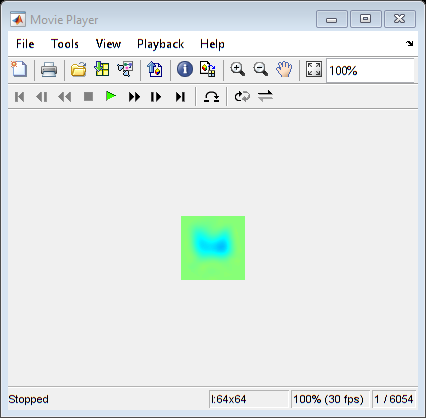

playVideo(imgFilt);

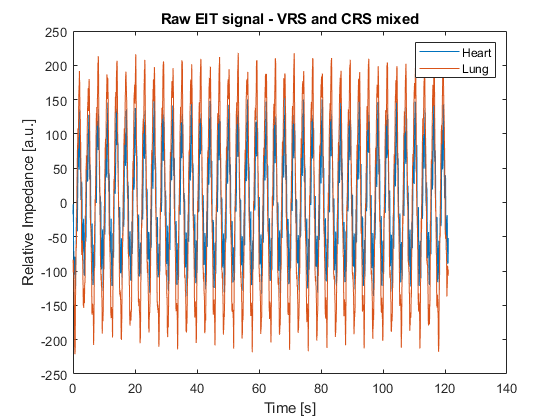

heartPix = [16,30];
lungPix = [30,40];

heartSig = squeeze(imgFilt(heartPix(1),heartPix(2),:));
lungSig = squeeze(imgFilt(lungPix(1),lungPix(2),:));

figure; plot(t, [heartSig,lungSig]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart","Lung"]);
title("Raw EIT signal - VRS and CRS mixed");

flatImg = reshape(imgFilt,64*64,[]);
dataWin = 64;
X = flatImg(:,1:dataWin-2);
X(isnan(X)) = 0;
Y = flatImg(:,2:dataWin-1);
Y(isnan(Y)) = 0;

% Initialize DMD class and properties
dmd = DMD();
rank = 24; % rank to truncate data to
predHor = 25; % prediction horizon (in samples)
tSim = (1:predHor)'/crs.Fs + t(end);

% Modified Exact DMD
tic
fitKoopman(dmd, X, Y, rank);
fitModes(dmd, X, Y, crs.Fs, 'exact-mod');
cleanModes(dmd);
interpModes(dmd);
toc

Elapsed time is 0.481388 seconds.


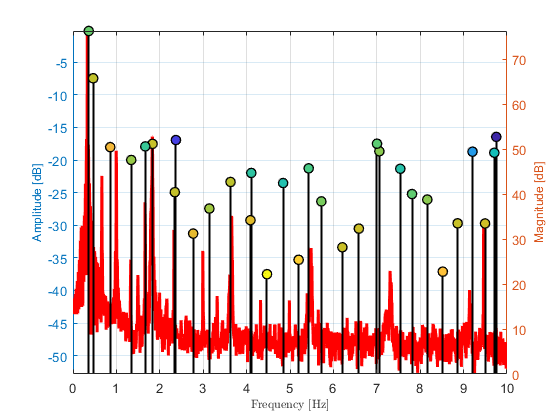

% Corrected frequency plot
powSpect(dmd, reshape(imgFilt,size(data,1) * size(data,2), [])', crs.Fs);

rank = -1;

tStart = 10;
tEnd = 13;
data = imgFilt(:,:,(tStart * crs.Fs):(tEnd * crs.Fs));
flatImg = reshape(data,size(data,1) * size(data,2), []);

predHor = size(data,3)+1;

Xout = hankelTransform(dmd,flatImg(:,1:end-1), 5);
Yout = hankelTransform(dmd,flatImg(:,2:end), 5);

tic
fitKoopman(dmd, Xout, Yout, rank, predHor);
fitModes(dmd, Xout, Yout, crs.Fs, 'hankel');
[Xcomps, Xtotal] = reconData(dmd, predHor, 1, 'disc');
cleanModes(dmd);
interpModes(dmd);
toc

Elapsed time is 8.296119 seconds.


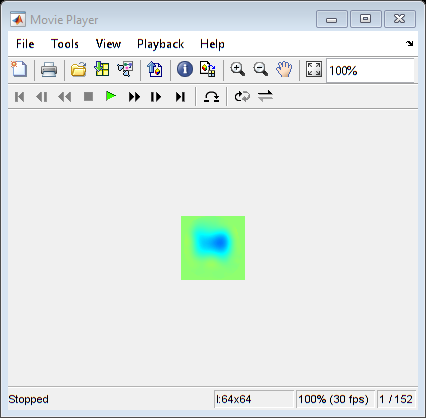

ans =   UnifiedScope with properties:

    InstanceNumber: 2
     Specification: [1×1 iptscopes.IMPlayScopeCfg]
        MessageLog: []
            Visual: [1×1 iptscopes.VideoVisual]
        DataSource: [1×1 matlabshared.scopes.source.WorkspaceSource]
            Parent: [1×1 Figure]


XtotalImg = reshape(real(Xtotal(1:4096,:)),64,64,[]);

playVideo(XtotalImg)

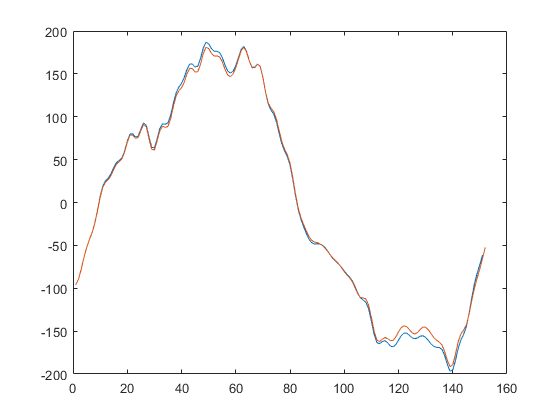

lung = squeeze(data(lungPix(1),lungPix(2),:));
lungRecon = squeeze(XtotalImg(lungPix(1),lungPix(2),:));
figure; plot(lung); hold on; plot([lungRecon]);

% Implement windowing
% Intialization window
w = 500; % samples
X1 = imgFilt(:,1:end-1);
X2 = imgFilt(:,2:end);

[n,m]  = size(X1);
Xdmd = zeros(1024, m+1);

% LIEW
% Initialization
w = 500;
initStart = 1;
initEnd = w + initStart - 1;

X = flatImg(:,initStart:initEnd);
Y = flatImg(:,initStart + 1:initEnd + 1);

fitKoopman(dmd, X, Y, 12, 'stream');

rho = 0.5;

% Define sliding window length
% Define window weights based on half-life

times = [];
signal = [];
for i = initStart + 1:size(flatImg,2) - 20
    % Build Hankel
    
    Xnew = flatImg(:,i);
    Ynew = flatImg(:,i + 20);
    
    tic
    updateStream(dmd, Xnew, Ynew, rho); % include Atilde update in updateStream + make rank property
    et = toc;
    
    [~, Xfinal] = reconData(dmd, 1, crs.Fs, 'cont');
    
    signal = [signal,Xfinal];
    times = [times;et];
end

figure; plot(times)
finalSignal = real(reshape(signal,64,64,[]));
playVideo(finalSignal)



for k = w+1:m
   tic
     sdmd2.update(X1(:,k),X2(:,k)); %update step
      
    %%%only for recon error
     [modes, lambda] = sdmd2.modes;
     b = pinv(modes)*X2(:,k);
    
      for j = 1:20
      
        tmp = lambda(j) * b(j) * modes(:,j);
        
        Xcomps{j}(:,k+1) = tmp;
        Xdmd(:,k+1) = Xdmd(:,k+1) + tmp;
        Xdmd(:,k+1) = tmp;
    end
    
   
   elapsed_time(k) = toc;
end

Matrix dimensions must agree.